HW11 Edge sharpening

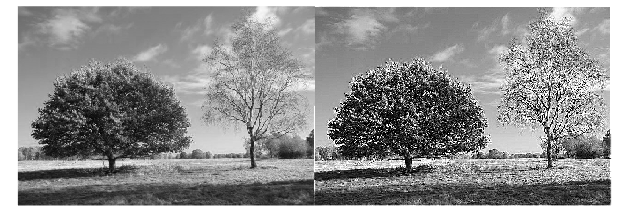

img = imread("../images/rgb2.jpg");
img = img(:, :, 1);
t = fspecial("unsharp", 0.5);
img_t = filter2(t, img);
montage([img, img_t])

HW12 Non linear filter

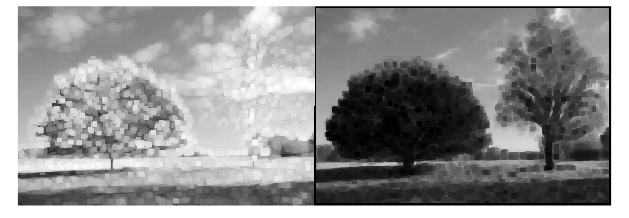

size = 10;
img_max = ordfilt2(img, size ^ 2, ones(size, size));
img_min = ordfilt2(img, 1, ones(size, size));
montage([img_max, img_min])

HW13 Median Filter

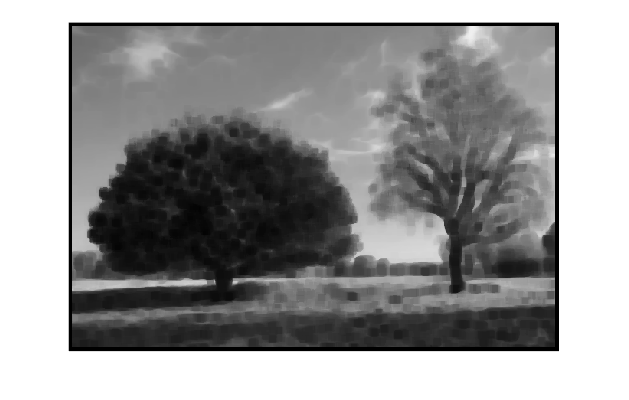

imshow(ordfilt2(img, 5, ones(size, size)))